# Online Directional Convolution

clear
close all

## Grid

grid = OctoGrid(2,2,2,100);

% add column
% grid.addBox(1.25,0.9,0,0.2,0.2,1.5)

% add wall
grid.addBox(0.2,0.8,0,1.6,0.1,1.5)

## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.232 1.027 0.971 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 

## Robot Base position

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

% start joints pose
q = [1.74582837386633
0.164551561035897
-2.28912954318266
-0.400811659236395
0.497594642234695
0.654743179774447
-0.0801486263893128];

## Calculate field

% Attractive
[grid_attractive] = attractive_field_3D(grid.grid, control_points(2,1:3), grid.resolution);

% Repulsive
kernel_size = 50; % how far should obstacles exert effect
sigma = 25 ; % how quickly should effect exerted by obstacles fall

% [grid_repulsive] = convolution_offline_3D(grid.grid,kernel_size,sigma);

% Total
Ka = 10; % attractive field coefficient
Kr = -5; % repulsive field coefficient

% total field is a weighted sum of both
% grid_total_field = Ka * grid_attractive + Kr * grid_repulsive;

## Path planning

[joints_positions, EE_positions, goal_distances, q_velocities, ee_velocities, values_secondary] = ObstacleGrid_RTConvolution_OnePoint(grid, grid_attractive, control_points(2,1:3), Tbase, q,'avoid_task', false, 'mid_joints', true);
[joints_positions_at, EE_positions_at, goal_distances_at, q_velocities_at, ee_velocities_at, values_secondary_at] = ObstacleGrid_RTConvolution_OnePoint(grid, grid_attractive, control_points(2,1:3), Tbase, q,'avoid_task', true, 'mid_joints', true);

## Show results

f1 = figure;
showMovementPanda(grid, [], control_points, joints_positions_at, EE_positions_at, values_secondary_at, Tbase)

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


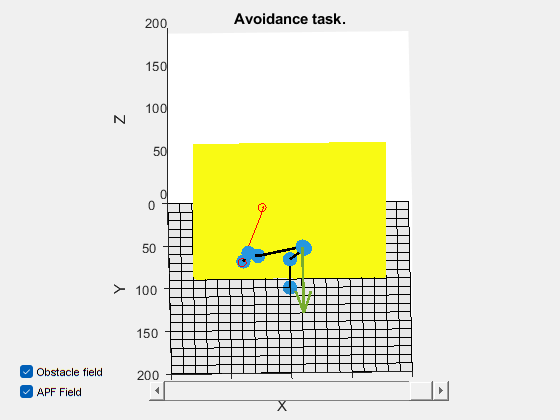

title('Avoidance task.')

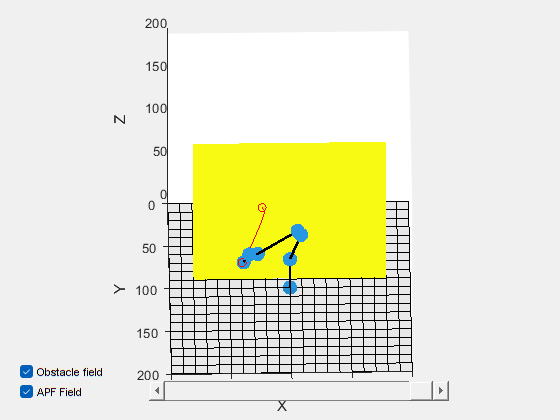

Index exceeds the number of array elements. Index must not exceed 0.

Error in showMovementPanda (line 104)
    for i = 1:1:size(values_APF(1).xyz,1)        


f2 = figure;
showMovementPanda(grid, [], control_points, joints_positions, EE_positions, values_secondary, Tbase)

title('No avoidance task.')